%Simulation
amax = 110;
g = -9.81;
dt = 0.01;
t = linspace(0,15,15/dt);
A = [1 dt 0.5*dt^2; 0 1 dt; 0 0 1];
x = zeros(3,length(t));
prev_x = zeros(3,length(t));
a_sim = (0 + (amax - 0)/0.8*t).*(t>0 & t<=0.8)+amax.*(t>0.8 & t <= 0.9)+(amax + (g - amax)/0.1*(t-0.9)).*(t>0.9 & t<1)+g.*(t>=1);

for i = 1:length(t)-1
    prev_x(3,i) = a_sim(i);
    x(:,i) = A*prev_x(:,i);
    prev_x(1,i+1) = x(1,i);
    prev_x(2,i+1) = x(2,i);
    if x(1,i)<0
        break
    end
end

s_n = x(1,:)+(5.985.*randn(1,length(t)));
v_n = x(2,:)+(2.*randn(1,length(t)));
a_n = x(3,:)+(0.0346.*randn(1,length(t)));

%Measurement begins
h_e =zeros(length(t),1); %Initial guess for height

a = 0;
v = 0;
h = 0;

p = 1 %Estimate variance of uncertaintys

p = 1

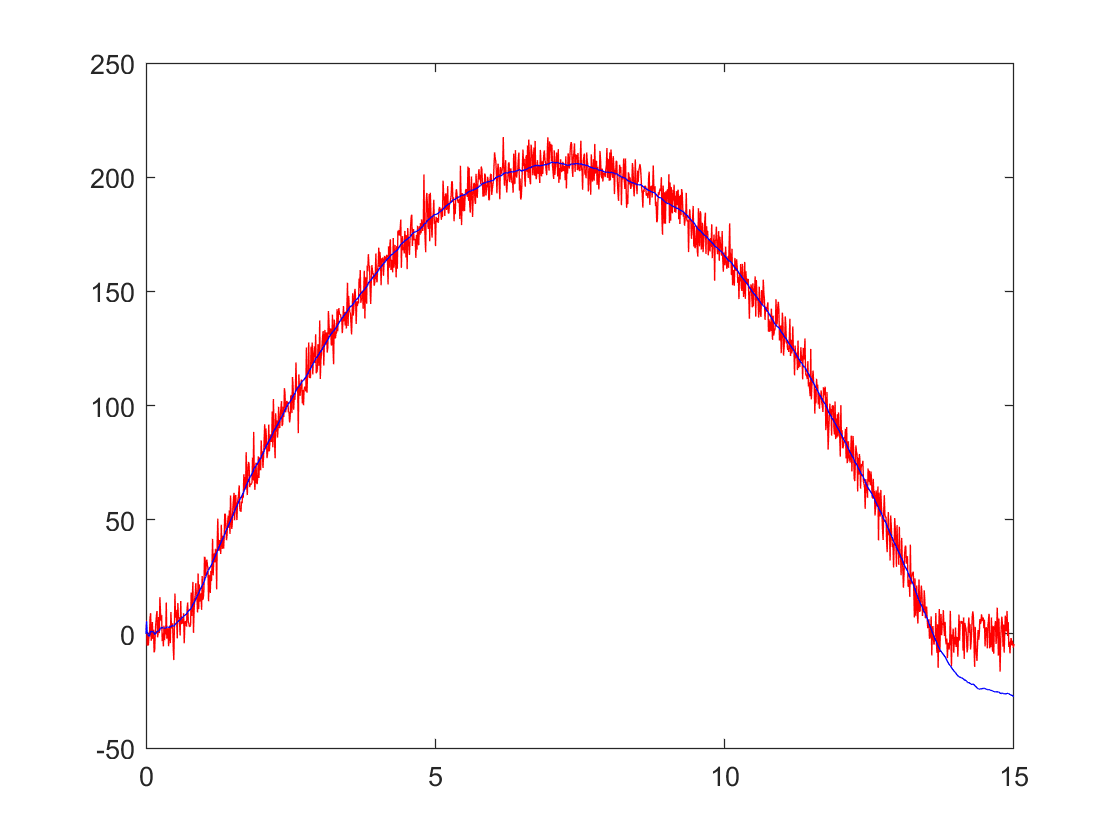

q = 0.000025; %Noise covariance
r = 0.05; %Measurement uncertainty
K = 0;

for i = 2:length(t)
    a = a_n(i);
    v = v + a*dt;
    h = h + dt*v +0.5*dt*dt*a; %State extrapolation
    p = p + q; %Covariance extrapolation
    K = p / (p +r); %Kalman gain
    h = h + K*(s_n(i) - h); %State update
    p = (1-K) * p; % Covariance update
    h_e(i,:) = h;
end
    
plot(t, s_n, 'r');
hold on
plot(t, h_e, 'b');